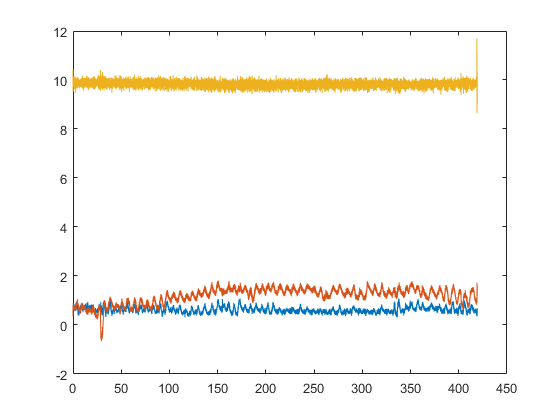


time =

  0×0 empty cell array


accel =

  0×0 empty cell array



N = 23288

chunk_sz = 60

chunks = 10

chunk_sz_index = 3333

front_trim = 3

index_front = 168

MotionData = struct with fields:
            Accel: [23288×3 double]
      Orientation: [23287×3 double]
           AngVel: [23287×3 double]
          t_Accel: [23121×1 double]
    t_Orientation: [23287×1 double]
         t_AngVel: [23287×1 double]
       accel_rate: 55.5556
      orient_rate: 55.5556
      AngVel_rate: 55.5556



chunked_Accel =

  0×0 empty cell array


chunked_t_Accel =

  0×0 empty cell array



i = 2

N = 23288

chunk_sz = 60

chunks = 10

chunk_sz_index = 3333

front_trim = 63

index_front = 3501

MotionData = struct with fields:
            Accel: [23288×3 double]
      Orientation: [23287×3 double]
           AngVel: [23287×3 double]
          t_Accel: [19788×1 double]
    t_Orientation: [23287×1 double]
         t_AngVel: [23287×1 double]
       accel_rate: 55.5556
      orient_rate: 55.5556
      AngVel_rate: 55.5556



chunked_Accel =

  0×0 empty cell array


chunked_t_Accel =

  0×0 empty cell array



i = 3

N = 23288

chunk_sz = 60

chunks = 10

chunk_sz_index = 3333

front_trim = 123

index_front = 6834

MotionData = struct with fields:
            Accel: [23288×3 double]
      Orientation: [23287×3 double]
           AngVel: [23287×3 double]
          t_Accel: [16455×1 double]
    t_Orientation: [23287×1 double]
         t_AngVel: [23287×1 double]
       accel_rate: 55.5556
      orient_rate: 55.5556
      AngVel_rate: 55.5556



chunked_Accel =

  0×0 empty cell array


chunked_t_Accel =

  0×0 empty cell array



i = 4

N = 23288

chunk_sz = 60

chunks = 10

chunk_sz_index = 3333

front_trim = 183

index_front = 10168

MotionData = struct with fields:
            Accel: [23288×3 double]
      Orientation: [23287×3 double]
           AngVel: [23287×3 double]
          t_Accel: [13121×1 double]
    t_Orientation: [23287×1 double]
         t_AngVel: [23287×1 double]
       accel_rate: 55.5556
      orient_rate: 55.5556
      AngVel_rate: 55.5556



chunked_Accel =

  0×0 empty cell array


chunked_t_Accel =

  0×0 empty cell array



i = 5

N = 23288

chunk_sz = 60

chunks = 10

chunk_sz_index = 3333

front_trim = 243

index_front = 13501

MotionData = struct with fields:
            Accel: [23288×3 double]
      Orientation: [23287×3 double]
           AngVel: [23287×3 double]
          t_Accel: [9788×1 double]
    t_Orientation: [23287×1 double]
         t_AngVel: [23287×1 double]
       accel_rate: 55.5556
      orient_rate: 55.5556
      AngVel_rate: 55.5556



chunked_Accel =

  0×0 empty cell array


chunked_t_Accel =

  0×0 empty cell array



i = 6

N = 23288

chunk_sz = 60

chunks = 10

chunk_sz_index = 3333

front_trim = 303

index_front = 16834

MotionData = struct with fields:
            Accel: [23288×3 double]
      Orientation: [23287×3 double]
           AngVel: [23287×3 double]
          t_Accel: [6455×1 double]
    t_Orientation: [23287×1 double]
         t_AngVel: [23287×1 double]
       accel_rate: 55.5556
      orient_rate: 55.5556
      AngVel_rate: 55.5556



chunked_Accel =

  0×0 empty cell array


chunked_t_Accel =

  0×0 empty cell array



i = 7

clear

filename = '7min_nathan_50hz.mat';
chunk_time = 60;
start_trim = 3;
[time,accel] = ChunkPlotData(filename,chunk_time,start_trim);

x = time{1}

x =          0
    0.0180
    0.0360
    0.0540
    0.0720
    0.0900
    0.1080
    0.1260
    0.1440
    0.1620


y = accel{1}(:,2)

y =     0.7441
    0.7142
    0.7298
    0.7909
    0.8558
    0.8415
    0.7525
    0.7609
    0.7897
    0.7298


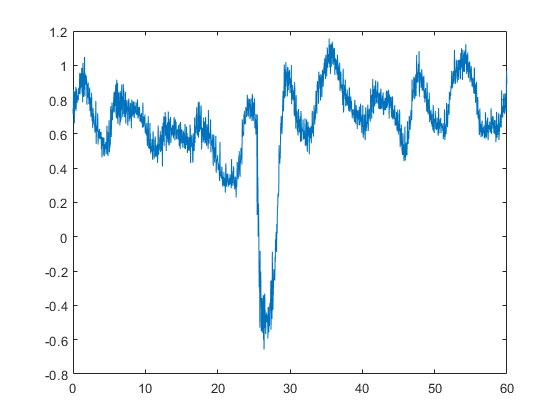

plot(x,y)


accelx = y;
accelx(length(accelx)+1) = 0;
for n = 7:length(accelx)-5
    norm_accel(n-1) = 1/7 * (accelx(n) + accelx(n-1)+ accelx(n-2)+ accelx(n-3)+ accelx(n-4)+ accelx(n-5)+ accelx(n-6)) ;
end
figure(112)
plot(x(1:end-1)',norm_accel,'b')

Error using plot
Vectors must be the same length.

hold on 
plot(x,accelx(1:end-1),'r')
hold off




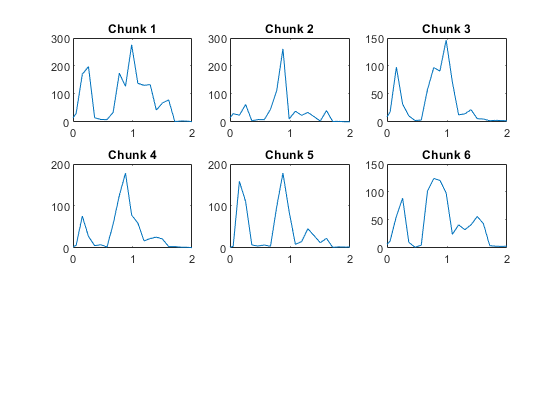

N = length(accel{1});
Fs = 55;
maxhbs = [];
figure(2);
for plotId = 1 : length(accel)
    data = accel{plotId};
    y_fft = fft(data(:, 2));
    y_fft_shift = abs(fftshift(y_fft));
    frequencies_shifted = Fs*linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);
    
    breath_low = 8/60;
    breath_high = 20/60;
    hb_low = 40/60;
    hb_high = 100/60;
    
    filter_inds = breath_high <= frequencies_shifted & frequencies_shifted <= hb_low | hb_high <= frequencies_shifted | frequencies_shifted <= breath_low;
    y_fft_shift(filter_inds) = y_fft_shift(filter_inds)/10;
    
    filter_inds = find(frequencies_shifted <= 0);
    y_fft_shift(filter_inds) = 0;

    subplot(3, 3, plotId);
    plot(frequencies_shifted, y_fft_shift) ;
    xlim([0 2])
    title(["Chunk " + plotId])
    
    range_hb =  find(hb_high >= frequencies_shifted & frequencies_shifted >= hb_low);
    range_br = find(frequencies_shifted >= breath_low & frequencies_shifted <= breath_high);
    maxhbs(plotId) = frequencies_shifted(find(y_fft_shift == max(y_fft_shift(range_hb))));
    maxbrs(plotId) = frequencies_shifted(find(y_fft_shift == max(y_fft_shift(range_br))));
end

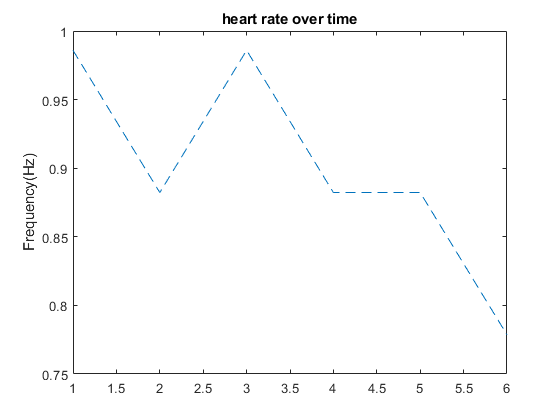


figure(3)
plot(maxhbs,"--")
title(["heart rate over time"])
ylabel(["Frequency(Hz)"])

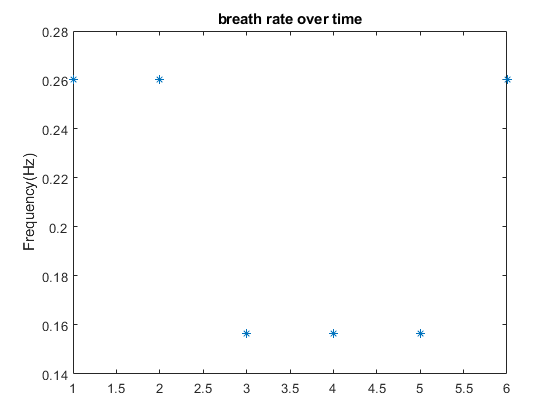


figure(4)
plot(maxbrs,"*")
title(["breath rate over time"])
ylabel(["Frequency(Hz)"])